# FIR filter design example

We will design an FIR filter whose transfer function approximates a desired form.

Our target transfer function is zero outside some specified frequency interval and parabolic inside it.

%Boundary points of the parabola
f1 = 100; %Hz
f2 = 250; %Hz (f2 > f1)

Set up the frequency values at which to specify the transfer function. These values do not have to be uniformly spaced but we will make it so here. 

maxFreq = 1024;%Hz
f = 0:2:maxFreq;

Get the parabola,

targetTf = (f-f1).*(f2-f);

and set the transfer function to zero outside the boundary points.

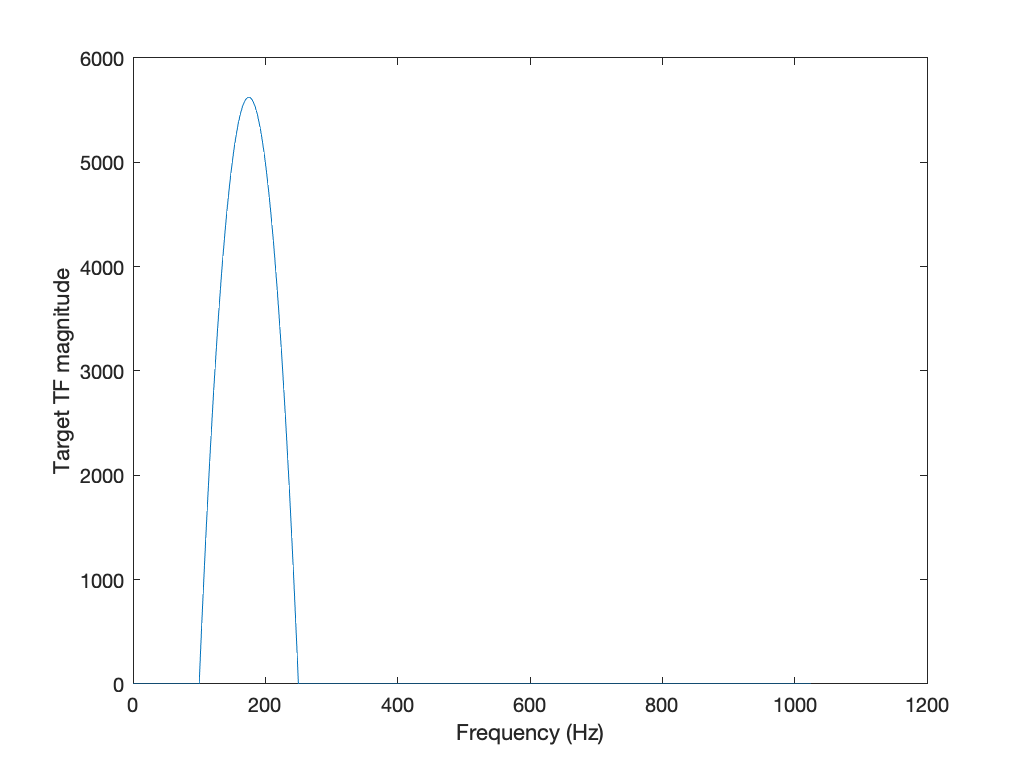

targetTf(f<f1 | f>f2) = 0;
trgtFig = figure;
plot(f,targetTf);
xlabel('Frequency (Hz)');
ylabel('Target TF magnitude');

Design the digital filter using the FIR2 function. Note that from the Nyquist theorem, the sampling frequency to use for generating any input signal to the filter must be twice the maximum frequency value.

%Sampling frequency
fs = 2*maxFreq;
%Filter order
fN = 50;
b = fir2(fN,f/(fs/2),targetTf);

Get the impulse response of the designed filter.

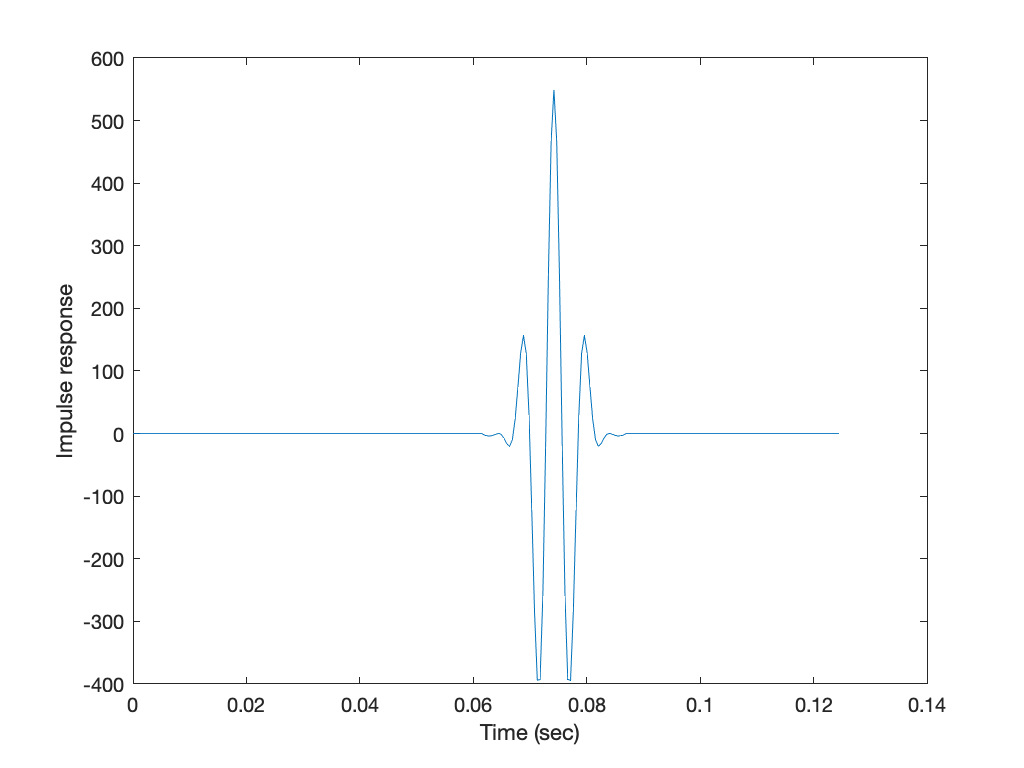

%Number of samples in impulse input sequence
nSamples = 256;
%Sampling times
timeVec = (0:(nSamples-1))/fs;
%Impulse response
impVec = zeros(1,nSamples);
impVec(floor(nSamples/2))=1; %Impulse in the middle
%Use efficient FFT based FIR filter implementation
impResp = fftfilt(b,impVec);
impFig = figure;
plot(timeVec,impResp);
xlabel('Time (sec)');
ylabel('Impulse response');

Get the transfer function: FFT of impulse response.

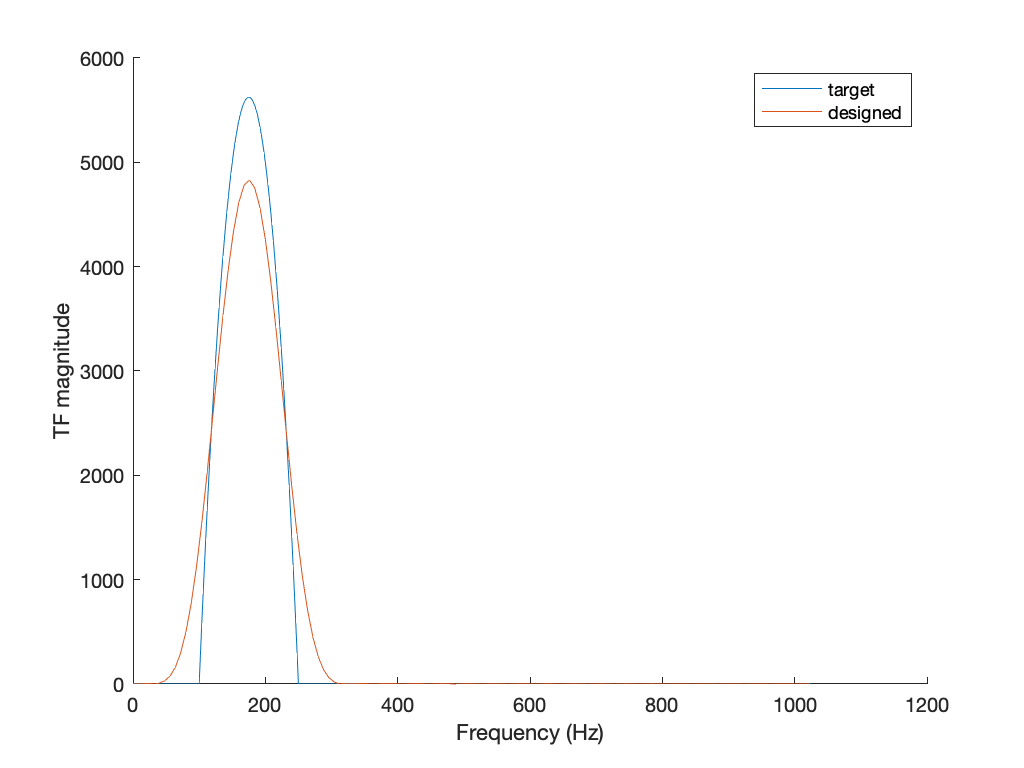

designTf = fft(impResp);

%Compare designed and target TF at positive DFT frequencies
trgtDsgn = figure;
hold on;
plot(f,targetTf);
kNyq = floor(nSamples/2)+1;
posFreq = (0:(kNyq-1))/(nSamples/fs);
plot(posFreq,abs(designTf(1:kNyq)));
xlabel('Frequency (Hz)');
ylabel('TF magnitude');
legend('target','designed')

## Apply the designed filter

We will apply the designed filter to the [quadratic chirp signal](matlab:open('../SIGNALS/signals.mlx')). We will generate the signal over a longer time interval than used for the impulse response. 

nSamplesSig = 4096;
timeVecSig = (0:(nSamplesSig-1))/fs;

The parameters of the signal that control the instantaneous frequency are,

a1=50;
a2=50;
a3=20;
A = 10;
disp(['Minimum frequency ',num2str(a1),' Hz']);

Minimum frequency 50 Hz


disp(['Maximum frequency ',num2str(a1+a2*timeVecSig(end)+3*a3*timeVecSig(end)^2),' Hz']);

Maximum frequency 389.8584 Hz


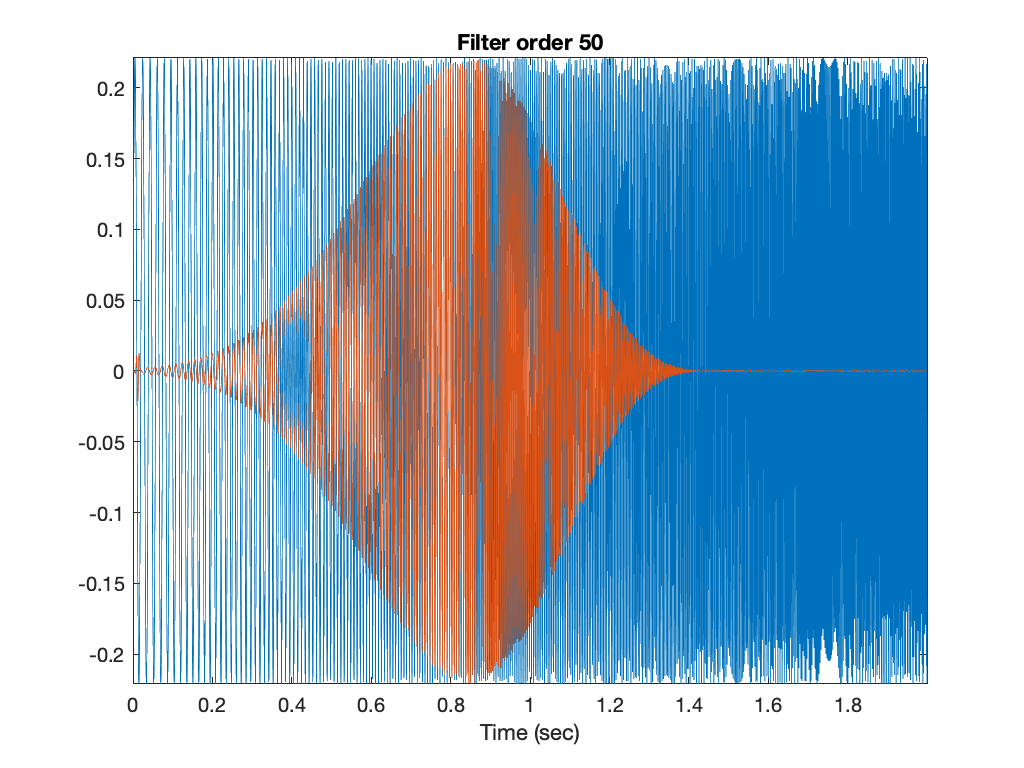

addpath ../SIGNALS
sigVec = crcbgenqcsig(timeVecSig,A,[a1,a2,a3]);
qcFiltFig = figure;
plot(timeVecSig,sigVec);
hold on;
filtSigVec = fftfilt(b,sigVec);
axis tight;
plot(timeVecSig,filtSigVec*max(sigVec)/max(filtSigVec));
xlabel('Time (sec)');
title(['Filter order ', num2str(fN)]);